A = [1 0.5 0 0;
     0 0.2 0.2 0;
     0 0.5 0.2 1;
     0 0 0 1]

A =     1.0000    0.5000         0         0
         0    0.2000    0.2000         0
         0    0.5000    0.2000    1.0000
         0         0         0    1.0000



B = [0.5; 1; 0; 1]

B =     0.5000
    1.0000
         0
    1.0000



C = [0.5 0.2 1 0]

C =     0.5000    0.2000    1.0000         0



desired_ob_poles = [complex(-0.3,0.5) complex(-0.3,-0.5) -1 -1.5]

desired_ob_poles =   -0.3000 + 0.5000i  -0.3000 - 0.5000i  -1.0000 + 0.0000i  -1.5000 + 0.0000i



Qc = ctrb(A,B);
det(Qc);
%system is completely controllable

U = ctrb(A',C')

U =     0.5000    0.5000    0.5000    0.5000
    0.2000    0.7900    0.5280    0.4586
    1.0000    0.2400    0.2060    0.1468
         0    1.0000    1.2400    1.4460


I = eye(4,4);
U_inverse = I/U

U_inverse =    -5.0731    0.6574    3.4051    1.2000
  -31.3268    8.2267   14.0181    6.8000
  117.4728  -22.4254  -54.2513  -28.0000
  -79.0729   13.5414   36.8282   20.0000



p1 = U_inverse(4,:)

p1 =   -79.0729   13.5414   36.8282   20.0000



P = [p1;
     p1*(A');
     p1*(A')^2;
     p1*(A')^3;
     ]

P =   -79.0729   13.5414   36.8282   20.0000
  -72.3022   10.0739   34.1363   20.0000
  -67.2653    8.8420   31.8642   20.0000
  -62.8442    8.1413   30.7939   20.0000



coeff_1_alpha = charpoly(A')

coeff_1_alpha =     1.0000   -2.4000    1.7400   -0.2800   -0.0600



coeff_2_a = poly(desired_ob_poles)

coeff_2_a =     1.0000    3.1000    3.3400    1.7500    0.5100



coeff_1 = flip(coeff_1_alpha(1, 2:5));
coeff_2 = flip(coeff_2_a(1, 2:5));

m_transpose = (coeff_2 - coeff_1)*P

m_transpose =  -645.1128   87.0928  310.6378  194.0000



m = m_transpose'

m =  -645.1128
   87.0928
  310.6378
  194.0000




initial_cond =[0.9 ,0.5 ,-0.5 ,0.75];

f = @(t, e) t*(A-m*C)*e

f = function_handle with value:
    @(t,e)t*(A-m*C)*e



[t,y]=ode45(f,[0,10],initial_cond)

t =          0
    0.0610
    0.1220
    0.1831
    0.2441
    0.3051
    0.3661
    0.4271
    0.4882
    0.5635


y =     0.9000    0.5000   -0.5000    0.7500
    0.9632    0.4918   -0.5277    0.7330
    1.1707    0.4646   -0.6195    0.6768
    1.5707    0.4121   -0.7985    0.5667
    2.2394    0.3240   -1.1013    0.3800
    3.2775    0.1867   -1.5763    0.0863
    4.8032   -0.0155   -2.2804   -0.3501
    6.9391   -0.2991   -3.2727   -0.9662
    9.8065   -0.6804   -4.6115   -1.7988
   14.5201   -1.3075   -6.8222   -3.1758


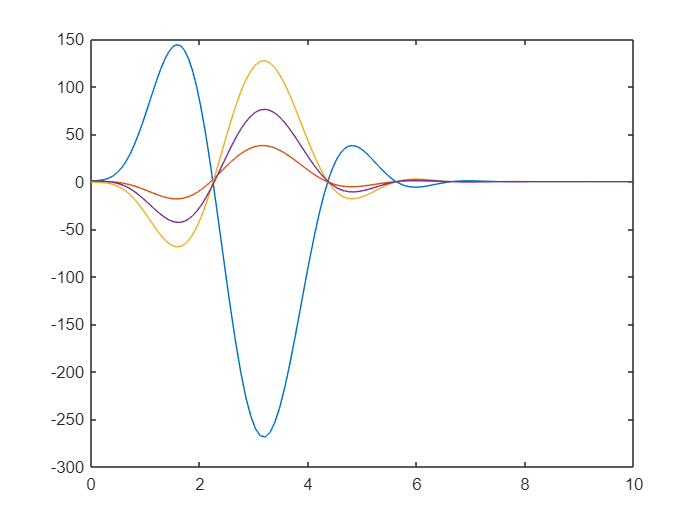


plot(t,y)